I = imread("im.jpg");
G = rgb2gray(I);

[Gr,S,r_k] = ecualizacion(G);


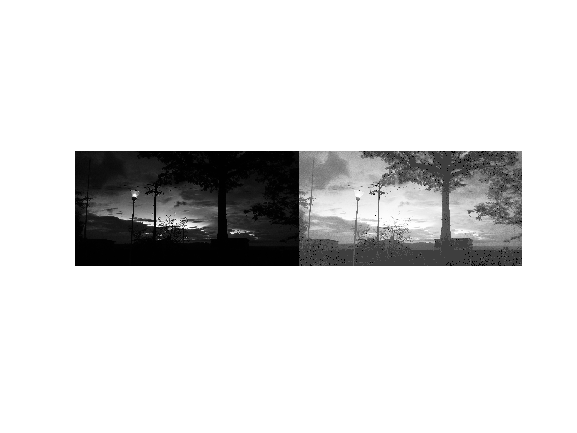

figure
imshow(cat(2, G, Gr))

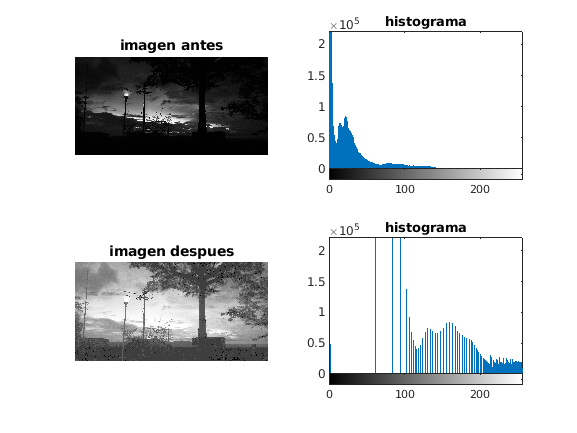

imhist(G)
figure
subplot(2,2,1); imshow(G); title("imagen antes");
subplot(2,2,2); imhist(G); title("histograma");
subplot(2,2,3); imshow(Gr); title("imagen despues");
subplot(2,2,4); imhist(Gr); title("histograma");

S

S =      2
    62
    84
    95
   102
   106
   109
   112
   114
   116


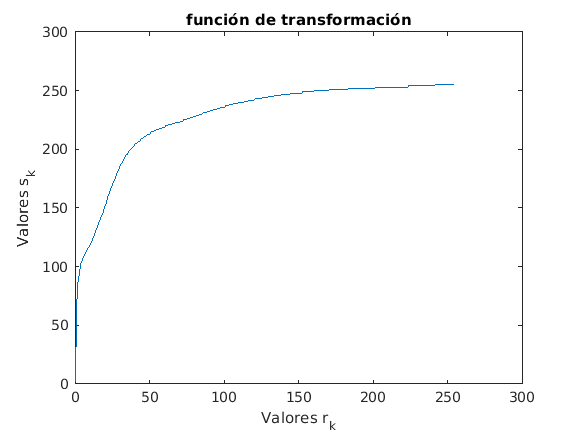

figure
ax2 = subplot(1,1,1);
plot(ax2,r_k,S);
title(ax2,'función de transformación');
ylabel(ax2,'Valores s_k');
xlabel(ax2,'Valores r_k');

I = imread("im.jpg");

I_R = I(:,:,1);  
I_G = I(:,:,2);
I_B = I(:,:,3);

[I_Re,SR,r_kr] = ecualizacion(I_R);
[I_Ge,SG,r_kg] = ecualizacion(I_G);
[I_Be,SB,r_kb] = ecualizacion(I_B);

K = cat(3, I_Re, I_Ge, I_Be);

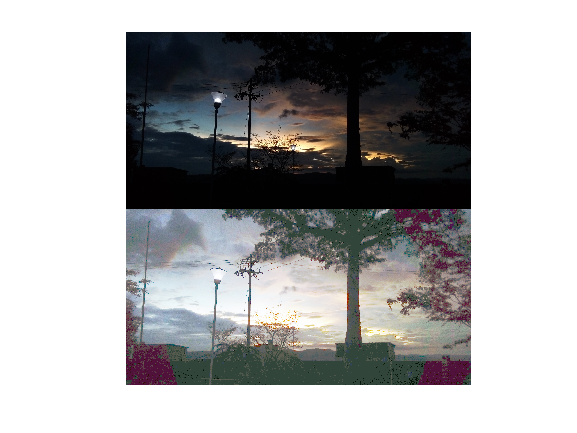

figure
imshow(cat(1, I, K))

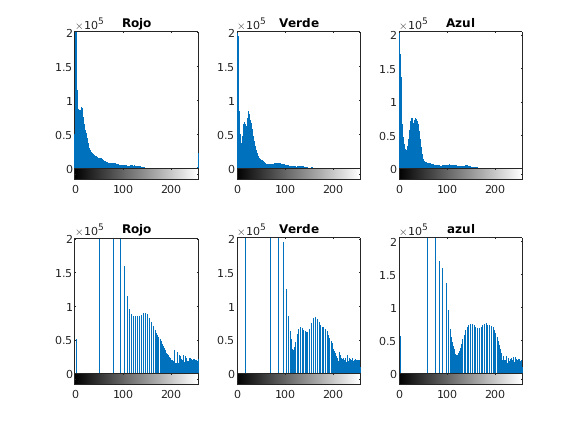


figure
subplot(2,3,1); imhist(I_R); title("Rojo");
subplot(2,3,2); imhist(I_G); title("Verde");
subplot(2,3,3); imhist(I_B); title("Azul");
subplot(2,3,4); imhist(I_Re); title("Rojo");
subplot(2,3,5); imhist(I_Ge); title("Verde");
subplot(2,3,6); imhist(I_Be); title("azul");

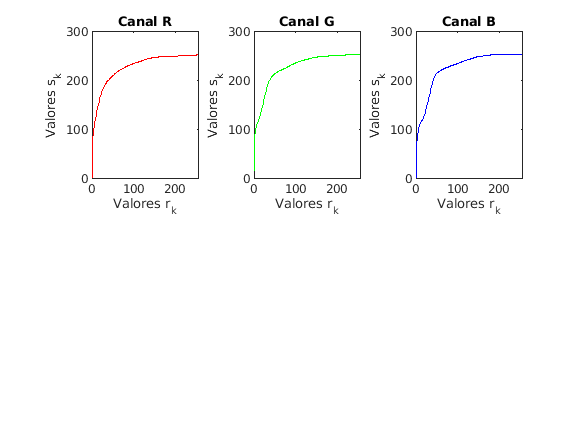

figure
ax1 = subplot(2,3,1);
plot(r_kr, SR, 'Red'); title('Canal R');
ylabel(ax1,'Valores s_k'); xlabel(ax1,'Valores r_k');
ax2 = subplot(2,3,2);
plot(r_kg, SG, 'Green'); title('Canal G');
ylabel(ax2,'Valores s_k'); xlabel(ax2,'Valores r_k');
ax3 = subplot(2,3,3);
plot(r_kb, SB, 'blue'); title('Canal B');
ylabel(ax3,'Valores s_k'); xlabel(ax3,'Valores r_k');